clear

syms theta1 theta2 theta3 theta4 theta5 theta6

A = [  0     -1     0.15
      200     0      0
     theta3 theta4 theta5 ];
B = [  0
       0
     theta6];
C = [0 1 0];
graybox = struct('A',A,'B',B,'C',C);
clear theta1 theta2 theta3 theta4 theta5 theta6

A = [-19.42  5.333    3.505
     -12.13 -0.6035 -11.48
      16.31 14.9     -4.98 ];
B = [-1.722
     -0.6439
      1.727 ];
C = [10.85 -6.926 8.238];
blackbox = ss(A,B,C,0);
clear A B C

sol = gray3sid(blackbox, graybox, 'Method','similarityTransform');
disp(sol.parameters.')

$$\left(\begin{array}{cccc} \theta_{3} & \theta_{4} & \theta_{5} & \theta_{6} \end{array}\right)$$

disp(sol.parameter_values.')

 -600.0783   -9.9725  -25.0035  -99.9225



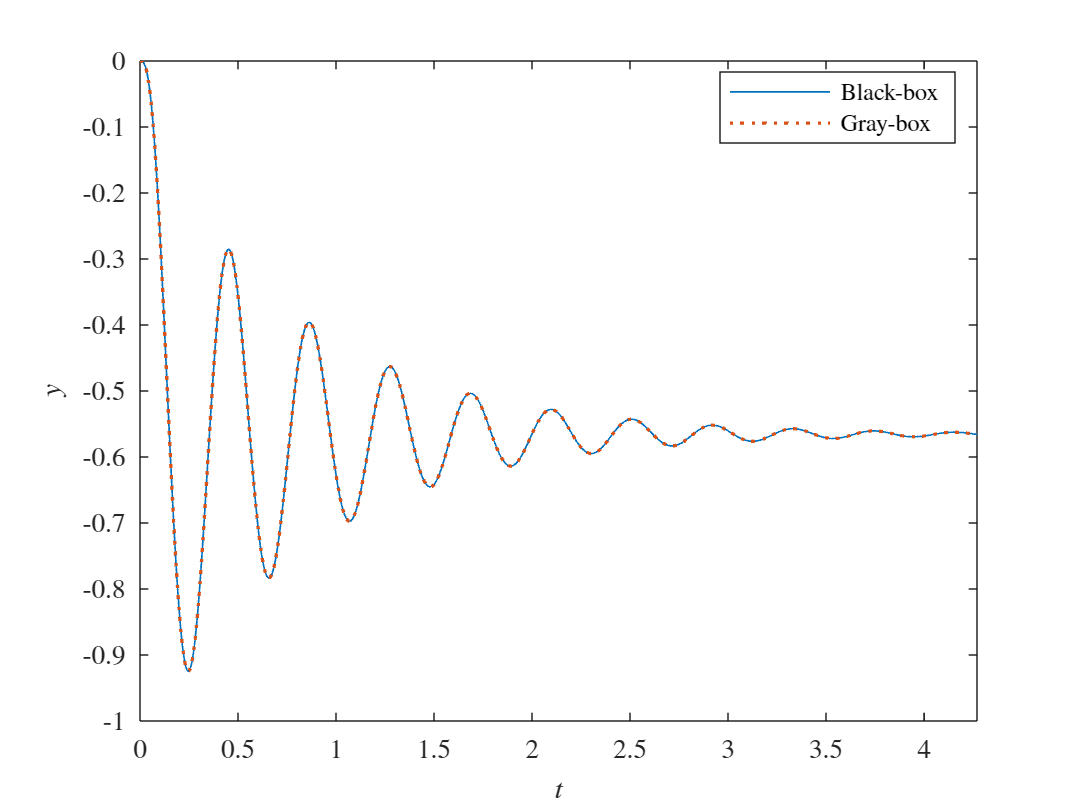


figure
hold on
[y,t] = step(blackbox);
plot(t, y, '-', 'DisplayName','Black-box', 'LineWidth',0.5)
[y,t] = step(sol.sys);
plot(t, y, ':', 'DisplayName','Gray-box',  'LineWidth',1)
legend('Location','best')
xlabel('$t$')
ylabel('$y$')
xlim([min(t) max(t)])
box on

clear

syms theta1 theta2 theta3

A = [1 theta1
     1 theta3];
B = [theta2
       1   ];
C = [1 0];
graybox = struct('A',A,'B',B,'C',C);
clear theta1 theta2 theta3

A = [177.776963379520  -496.711190701046
      64.3476596331393 -179.776963379520];
B = [3.72290476694050
     1.33660669226990];
C = [14.3600000000000  -37.7530000000000];
blackbox = ss(A,B,C,0);
clear A B C

sol = gray3sid(blackbox, graybox, 'Method','similarityTransform');
disp(sol.parameters.')

$$\left(\begin{array}{ccc} \theta_{1} & \theta_{2} & \theta_{3} \end{array}\right)$$

disp(sol.parameter_values.')

   -5.0000    3.0000   -3.0000



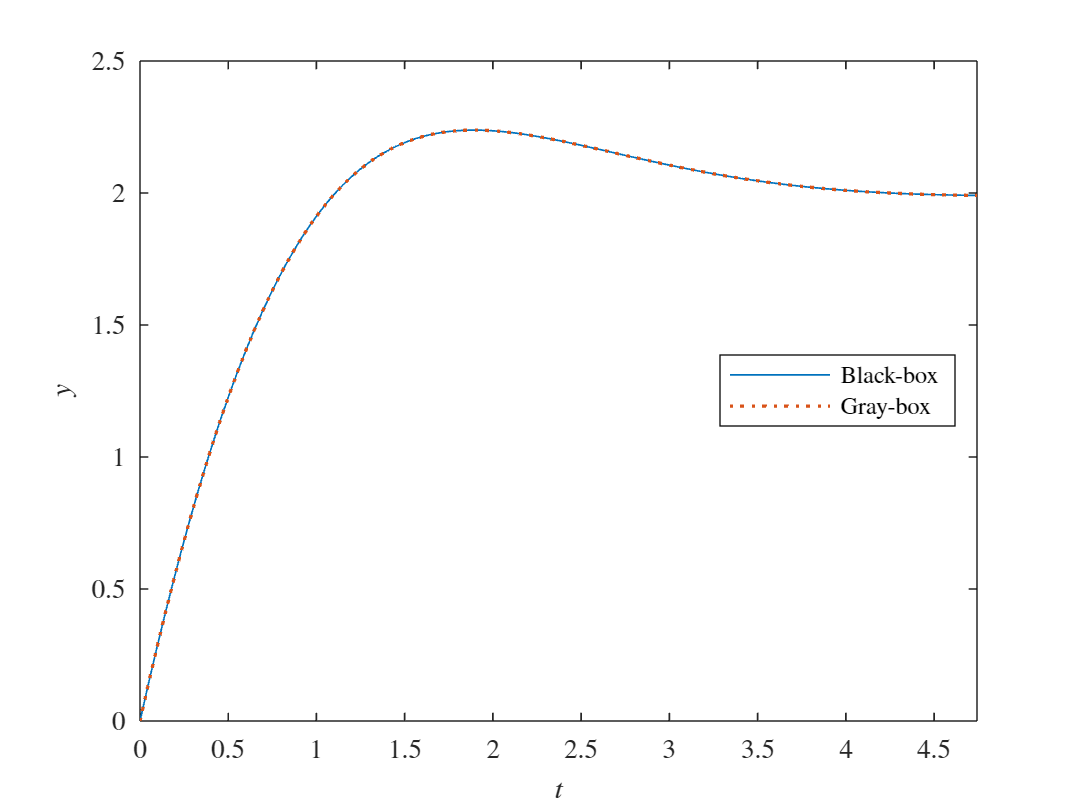


figure
hold on
[y,t] = step(blackbox);
plot(t, y, '-', 'DisplayName','Black-box', 'LineWidth',0.5)
[y,t] = step(sol.sys);
plot(t, y, ':', 'DisplayName','Gray-box',  'LineWidth',1)
legend('Location','best')
xlabel('$t$')
ylabel('$y$')
xlim([min(t) max(t)])
box on